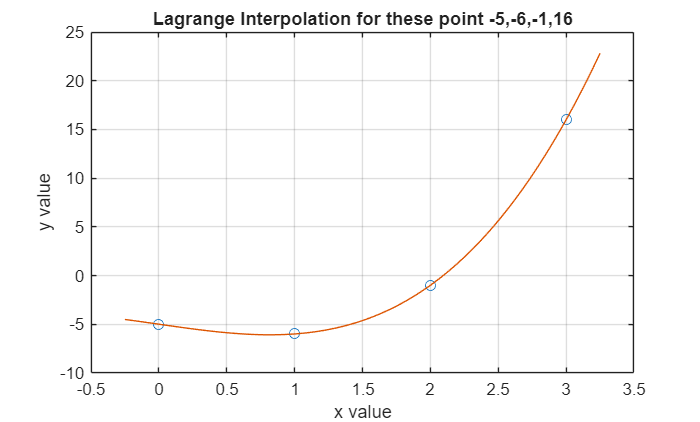

%part 1
x=0:3;
y=[-5,-6,-1,16];
u= -.25:.01:3.25;
v=polyinterp(x,y,u);
plot(x,y,'o',u,v,'-');
grid on;
title('Lagrange Interpolation for these point -5,-6,-1,16');
xlabel('x value');
ylabel('y value');

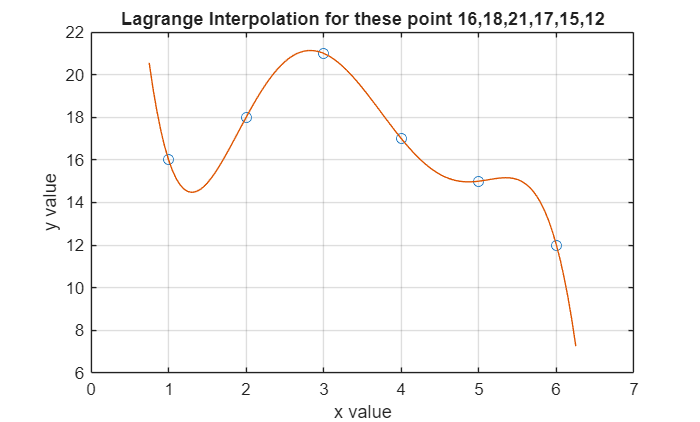



x=1:6;
y=[16,18,21,17,15,12];
u=.75:.05:6.25;
v=polyinterp(x,y,u);
plot(x,y,'o',u,v,'-');
grid on;
title('Lagrange Interpolation for these point 16,18,21,17,15,12');
xlabel('x value');
ylabel('y value');


% ---- Lagrange interpolation function ----
function v = polyinterp(x, f, u)
    v = zeros(size(u));
    
    for k=1:length(u)
        
        for j=1:length(x)
            l_j = 1;
            for i=1:length(x)
                if j ~= i
                    l_j = l_j*(u(k)-x(i))/(x(j)-x(i));
                end
            end

            v(k) = v(k) + (l_j*f(j));
        end  
    end
end

% DATA
x = [-1.00, -0.96, -0.65, 0.10, 0.40, 1.00];
y = [-1.00, -0.1512, 0.3860, 0.4802, 0.8838, 1.00];

% grid for plotting on [-1,1]
xx = linspace(-1,1,500);

% 1) piecewise linear (MATLAB: interp1 with 'linear')
yy_linear = interp1(x,y,xx,'linear');

% 2) global polynomial interpolation: use degree 5 polynomial (unique through 6 points)
coeffs_p5 = polyfit(x,y,5)    % coefficients highest->lowest

coeffs_p5 =    16.0018    0.0007  -20.0022   -0.0007    5.0004    0.0000


yy_poly = polyval(coeffs_p5, xx)

yy_poly =    -1.0000   -0.9014   -0.8059   -0.7136   -0.6243   -0.5380   -0.4547   -0.3742   -0.2966   -0.2218   -0.1498   -0.0804   -0.0137    0.0504    0.1120    0.1710    0.2276    0.2818    0.3336    0.3831    0.4304    0.4754    0.5182    0.5589    0.5975    0.6340    0.6685    0.7011    0.7317    0.7605    0.7874    0.8125    0.8358    0.8574    0.8773    0.8956    0.9122    0.9273    0.9409    0.9530    0.9636    0.9727    0.9805    0.9869    0.9921    0.9959    0.9985    0.9998    1.0000    0.9990


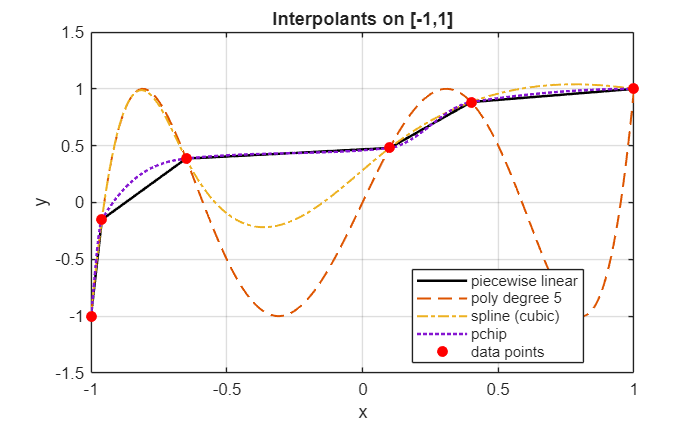


% 3) cubic spline (MATLAB spline, natural by default on ends)
yy_spline = spline(x,y,xx);

% 4) pchip (shape-preserving cubic Hermite)
yy_pchip = pchip(x,y,xx);

% Plot all
figure;
plot(xx, yy_linear, 'k-', 'LineWidth',1.5); hold on;
plot(xx, yy_poly, '--', 'LineWidth',1.2);
plot(xx, yy_spline, '-.', 'LineWidth',1.2);
plot(xx, yy_pchip, ':', 'LineWidth',1.5);
plot(x,y,'ro','MarkerFaceColor','r');
legend('piecewise linear','poly degree 5','spline (cubic)','pchip','data points',...
       'Location','best');
xlabel('x'); ylabel('y'); title('Interpolants on [-1,1]');
grid on; hold off;


% Evaluate at x=3 (extrapolation)
xq = 3;
val_linear = interp1(x,y,xq,'linear','extrap');
val_poly   = polyval(coeffs_p5, xq);
val_spline = ppval(spline(x,y), xq);    % spline extrapolates piecewise polynomial
val_pchip  = interp1(x,y,xq,'pchip','extrap');

fprintf('Values at x = 3 (extrapolation):\n');

Values at x = 3 (extrapolation):


fprintf(' piecewise linear: %g\n', val_linear);

 piecewise linear: 1.38733


fprintf(' polynomial (deg 5): %g\n', val_poly);

 polynomial (deg 5): 3363.42


fprintf(' spline (cubic): %g\n', val_spline);

 spline (cubic): 1.15973


fprintf(' pchip: %g\n\n', val_pchip);

 pchip: -0.812146




% --- Try to recover a low-degree polynomial (if it exists) ---
% Fit polynomials of increasing degree and check fit error
for deg = 0:5
    c = polyfit(x,y,deg);
    err = max(abs(polyval(c,x)-y));
    fprintf('deg %d  max residual on data = %.3e\n', deg, err);
end

deg 0  max residual on data = 1.266e+00
deg 1  max residual on data = 6.281e-01
deg 2  max residual on data = 4.918e-01
deg 3  max residual on data = 3.513e-01
deg 4  max residual on data = 3.197e-01
deg 5  max residual on data = 2.554e-15



% If one degree <= tolerance (say 1e-12) then polynomial of that degree fits exactly:
deg = 5; % unique interpolating degree for 6 points
c5 = coeffs_p5;

% Show coefficients nicely (rational approximation)
fprintf('\nDegree-5 polynomial coefficients (highest->lowest):\n');


Degree-5 polynomial coefficients (highest->lowest):


disp(c5);

   16.0018    0.0007  -20.0022   -0.0007    5.0004    0.0000




% Convert to rational approximations to look for small integer coefficients:
rats_c5 = rats(c5, 1e-10);   % returns strings; use vpa/sym if needed
fprintf('Rational approximation of coeffs (strings):\n');

Rational approximation of coeffs (strings):


disp(rats_c5);

 * * * * * *



% Optionally build symbolic polynomial and simplify (if Symbolic Toolbox available)
if license('test','symbolic_toolbox')
    sc = sym( vpa(c5, 16) );
    syms z
    P = 0;
    for k=1:length(sc)
        P = P + sc(k)*z^(length(sc)-k);
    end
    P = simplify(P);
    fprintf('Symbolic polynomial (simplified):\n');
    disp(P);
else
    fprintf('Symbolic toolbox not available: use rats or vpa to inspect coefficients.\n');
end

Symbolic polynomial (simplified):


$$16.001760721584691538055267301388\,z^{5}+0.00067181340732633124720324380163561\,z^{4}-20.002172969527723722649170667864\,z^{3}-0.00067947150908854276555454143604607\,z^{2}+5.0004122479430312964154836663511\,z+0.0000076581017608479240552261935182088$$

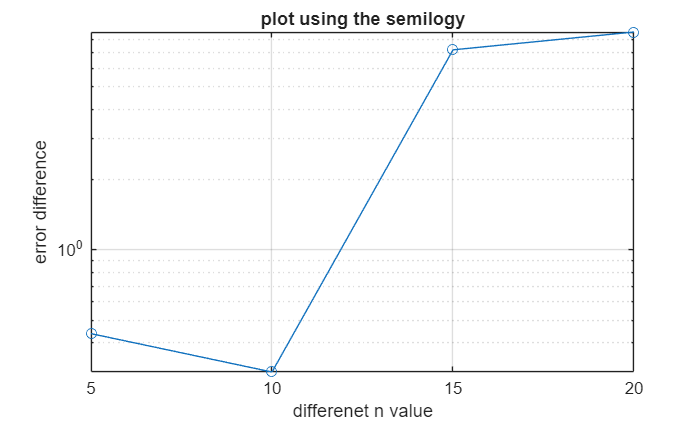



%part 4
g=@(x) 1./(1+25.*x.^2);

%are the point through which we test are polynomial interpolation 
points=linspace(-1,1,1000);

%are the point through which we build are polynomial
N=[5 10 15 20];

%we create a array of 4 in which we store the error of the polynomial. and
%these is calculate through taking difference by testing through 1000 point
err_poly=zeros(size(N));

%same storing the error 
err_spline=zeros(size(N));

%creating a figure name 1
figure(1);
%clear figure
clf;
%iterate over the array of 4 element
for k=1:length(N)
    %take that point in variable n (number of point to create the polynomial)
    n=N(k);

    %on x-axis we have n point 
    xnodes=linspace(-1,1,n);

    %on y axis corresponding to the xnode we haev same value
    ynodes=g(xnodes);

    %now construct the polynomial of n-1 degree
    polyEquation=polyfit(xnodes,ynodes,n-1);
    
    %p5 is an vector of length 1000 where we store the value of ynode from
    %the polynomial by putting the 1000 point one by one in the
    %polyEquation and then store it
    %{ calculated value }
    p5=polyval(polyEquation,points);

    %and as we know the function (g) then putting those 1000 point in the
    %function we will get the { actual value } at the xnode 
    
    %we are taking the max. error norm out of all the error
    err_poly(k)=max(abs(g(points)-p5));
end
%x-axis is N and y-axis is err_poly and semilogy is used for data
%visualization(plotting)
semilogy(N,err_poly,'o-');
grid on;
%showing the error in those input(how much error is there ) 
title('plot using the semilogy');
xlabel('differenet n value');
ylabel('error difference');

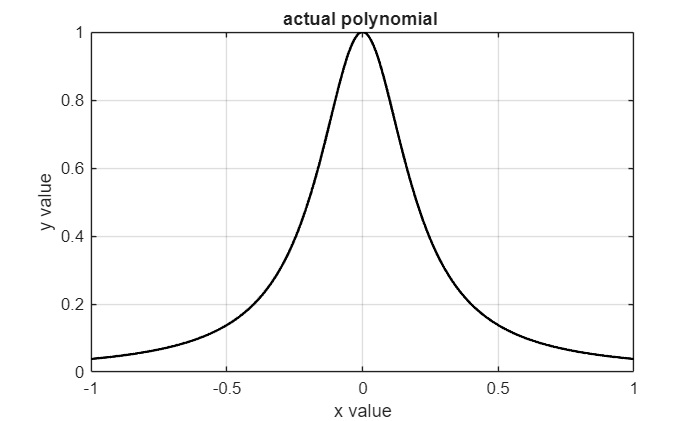


%actual graph
plot(points,g(points),'k','LineWidth',1.5);
grid on;
title('actual polynomial ');
xlabel('x value');
ylabel('y value');

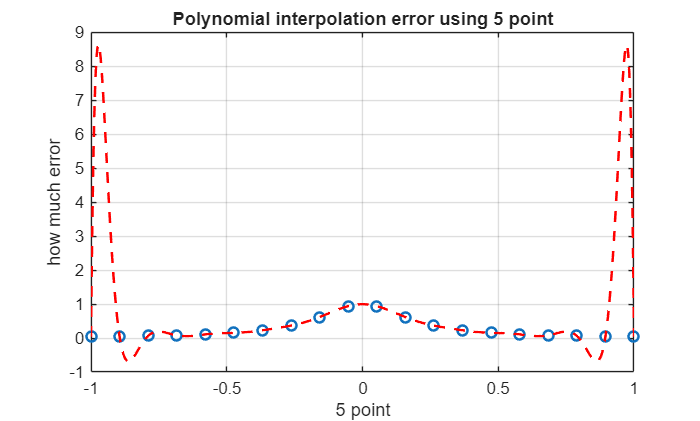



%showing wrt 5point how much error there will be
plot(xnodes,ynodes,'o',points,p5,'r--','LineWidth',1.5);
grid on;
title('Polynomial interpolation error using 5 point');
xlabel('5 point');
ylabel('how much error');

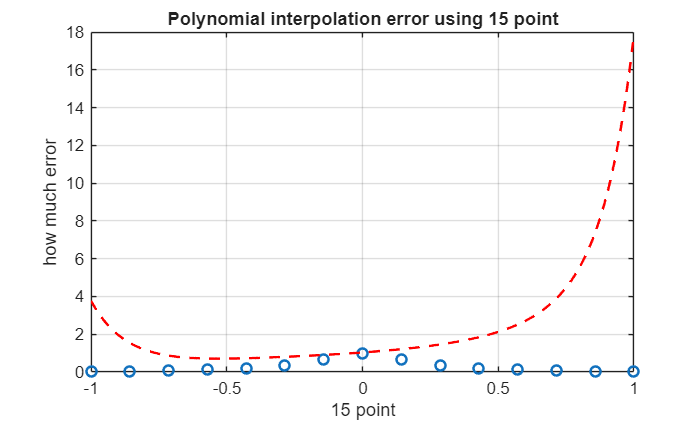



figure(2);
clf;

xnodes15=linspace(-1,1,15);
ynodes15=g(xnodes15);
polyEquation15=polyval(xnodes15,ynodes15,14);
p15=polyval(polyEquation15,points);
plot(xnodes15,ynodes15,'o',points,p15,'r--','Linewidth',1.5);
title('Polynomial interpolation error using 15 point');
xlabel('15 point');
ylabel('how much error');
grid on;

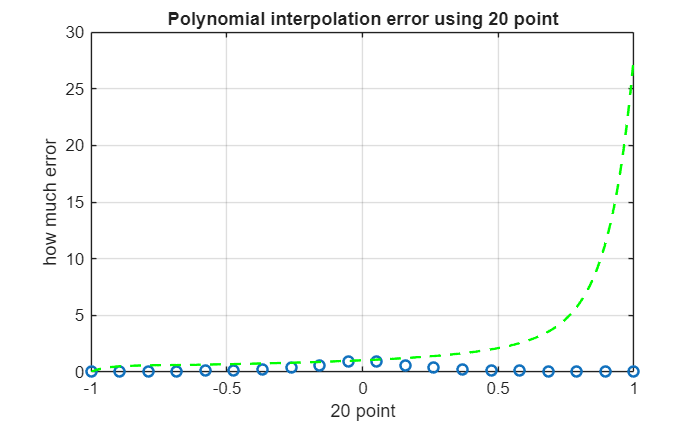


figure(3);
clf;

xnodes20=linspace(-1,1,20);
ynodes20=g(xnodes20);
polyEquation20=polyval(xnodes20,ynodes20,19);
p20=polyval(polyEquation20,points);
plot(xnodes20,ynodes20,'o',points,p20,'g--','Linewidth',1.5);
title('Polynomial interpolation error using 20 point');
xlabel('20 point');
ylabel('how much error');
grid on;

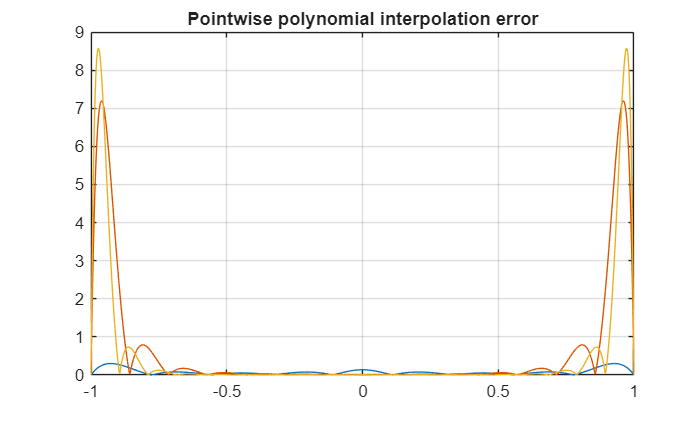




figure(4); clf;
for n = [10 15 20]
    xnodes = linspace(-1,1,n);
    pval = polyval(polyfit(xnodes, g(xnodes), n-1), points);
    plot(points, abs(g(points)-pval), 'DisplayName',sprintf('n=%d',n)); hold on;
end
title('Pointwise polynomial interpolation error');
grid on;

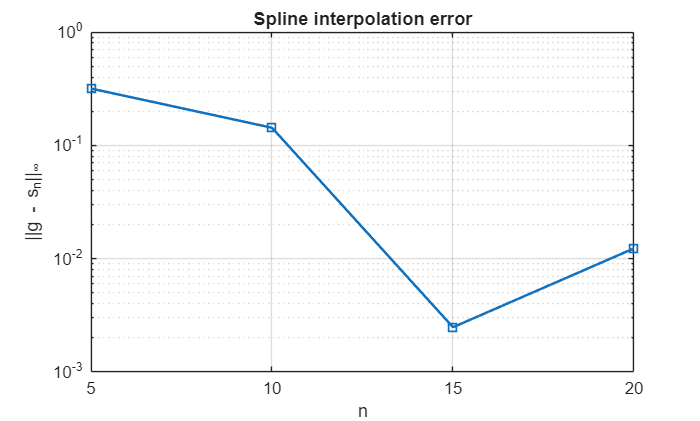



figure(5); clf;
for k = 1:length(N)
    n = N(k);
    xnodes = linspace(-1,1,n);
    ynodes = g(xnodes);
    sval = spline(xnodes, ynodes, points);
    err_spline(k) = max(abs(g(points) - sval));
end
semilogy(N, err_spline,'s-','LineWidth',1.5);
xlabel('n'); ylabel('||g - s_n||_\infty');
title('Spline interpolation error');
grid on;



%part 5

% Read CSV (assuming first column = Date, second column = Close Price)
%T = readtable(filename);
prices = 10000*[4.8620, 4.8691, 4.8732, 4.8438, 4.8479, 4.7942, 4.8241, 4.8760, 4.8464, 4.8312, 4.7875, 4.7894, 4.8219, 4.8220, 4.8793, 4.9375, 4.9948, 4.9927, 5.0983, 5.1874, 5.1640, 5.1085, 5.1608, 5.1178, 5.0967, 5.0910, 5.1712, 4.9336, 5.0389, 5.0487, 5.0634, 5.2299, 5.2691, 5.3154, 5.4891, 5.5414, 5.6097, 5.5104, 5.5234, 5.4610, 5.5524, 5.5382, 5.5101, 5.5066, 5.4918, 5.4013, 5.4802, 5.3596, 5.4659, 5.5233, 5.5009, 5.4854, 5.5276, 5.5326, 5.5445, 5.5060, 5.4876, 5.4959, 5.5535, 5.5459, 5.5329, 5.5571, 5.5616, 5.5598, 5.6105, 5.5650, 5.5807, 5.5699, 5.7050, 5.6994, 5.6640, 5.6481, 5.5149, 5.5554, 5.5975, 5.5545, 5.5785, 5.5567, 5.5832, 5.6529, 5.6565, 5.6694, 5.7235, 5.7530, 5.7376, 5.7558, 5.7050, 5.6825, 5.6939, 5.6943, 5.7200, 5.7340, 5.6843, 5.6781, 5.6709, 5.7111, 5.7232, 5.6524, 5.6559, 5.7253, 5.6918];data = [4.8620, 4.8691, 4.8732, 4.8438, 4.8479, 4.7942, 4.8241, 4.8760, 4.8464, 4.8312, 4.7875, 4.7894, 4.8219, 4.8220, 4.8793, 4.9375, 4.9948, 4.9927, 5.0983, 5.1874, 5.1640, 5.1085, 5.1608, 5.1178, 5.0967, 5.0910, 5.1712, 4.9336, 5.0389, 5.0487, 5.0634, 5.2299, 5.2691, 5.3154, 5.4891, 5.5414, 5.6097, 5.5104, 5.5234, 5.4610, 5.5524, 5.5382, 5.5101, 5.5066, 5.4918, 5.4013, 5.4802, 5.3596, 5.4659, 5.5233, 5.5009, 5.4854, 5.5276, 5.5326, 5.5445, 5.5060, 5.4876, 5.4959, 5.5535, 5.5459, 5.5329, 5.5571, 5.5616, 5.5598, 5.6105, 5.5650, 5.5807, 5.5699, 5.7050, 5.6994, 5.6640, 5.6481, 5.5149, 5.5554, 5.5975, 5.5545, 5.5785, 5.5567, 5.5832, 5.6529, 5.6565, 5.6694, 5.7235, 5.7530, 5.7376, 5.7558, 5.7050, 5.6825, 5.6939, 5.6943, 5.7200, 5.7340, 5.6843, 5.6781, 5.6709, 5.7111, 5.7232, 5.6524, 5.6559, 5.7253, 5.6918];

% Day indices
days_all = 0:1:100;       % All days
x = 0:5:100;            % Sampled days every 5 days
y = prices(1:5:end);% Corresponding prices

% Interpolation at all days
interp_values = polyinterp(x, y, days_all);

% calculating maximum interpolation error
interp_array=abs(prices - interp_values);
max_error = max(interp_array);
fprintf("max. absolute interpolation error(polynomial)  : %.4f\n", max_error);

max. absolute interpolation error(polynomial)  : 1599200.3265


fprintf("Is the Runge phenomenon evident in your plot : yes");

Is the Runge phenomenon evident in your plot : yes

fprintf("runge phenomenon can be seen in the polynomial interpolating graph")

runge phenomenon can be seen in the polynomial interpolating graph

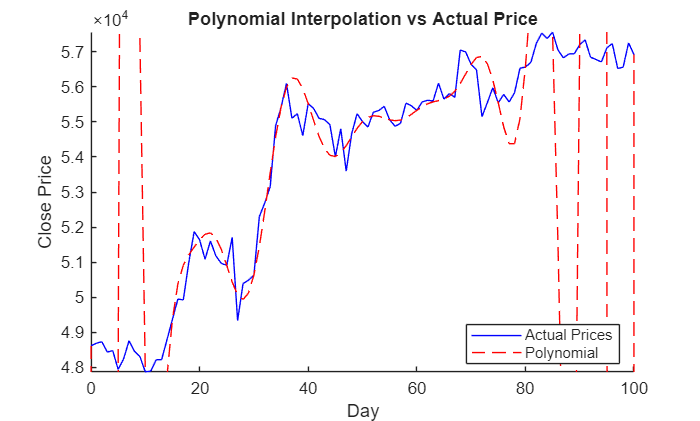


% ---- Plot ----
figure;
hold on;
plot(days_all, prices, 'b-');
plot(days_all, interp_values, 'r--');
legend("Actual Prices", "Polynomial", "Location", "Best");
xlabel('Day');
ylabel('Close Price');
title('Polynomial Interpolation vs Actual Price');
hold off;

% Zoom in (we can adjust limits)
xlim([0 100]);  % Only first 100 days
ylim([min(prices)-5, max(prices)+5]);


% Interpolation at all days
spline_values = spline(x, y, days_all);

% calculating maximum interpolation 
spline_array=abs(prices - spline_values);
spline_max_error = max(spline_array);
fprintf("max. absolute interpolation error(spline)  : %.4f\n", spline_max_error);

max. absolute interpolation error(spline)  : 1250.2514


fprintf("Is the Runge phenomenon evident in your plot : no");

Is the Runge phenomenon evident in your plot : no

fprintf("runge phenomenon is not seen in the spline graph")

runge phenomenon is not seen in the spline graph

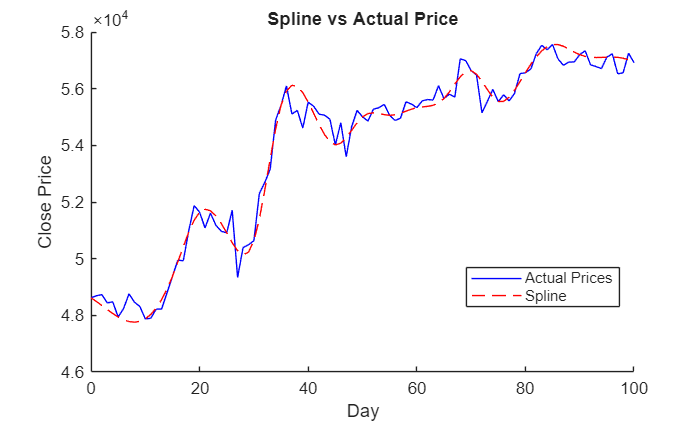


% ---- Plot for spline ----
figure;
hold on;
plot(days_all, prices, 'b-');
plot(days_all, spline_values, 'r--');
legend("Actual Prices", "Spline", "Location", "Best");
xlabel('Day');
ylabel('Close Price');
title('Spline vs Actual Price');
hold off;

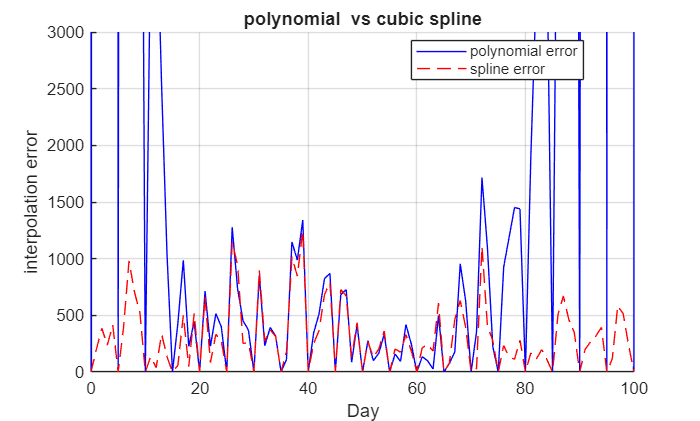


% --- Combined plot for polynomial interpolation and spline---
figure;
hold on;
plot(days_all, interp_array, 'b-');
plot(days_all, spline_array, 'r--');
legend("polynomial error","spline error","Location", "Best");
xlabel('Day');
ylabel('interpolation error');
title('polynomial  vs cubic spline');
xlim([0 100]);
ylim([0, 3000]);
grid on;
hold off;